# **Segmentation and Region Extraction**

## Image 1 - Get Regions

- **Import and crop image.**

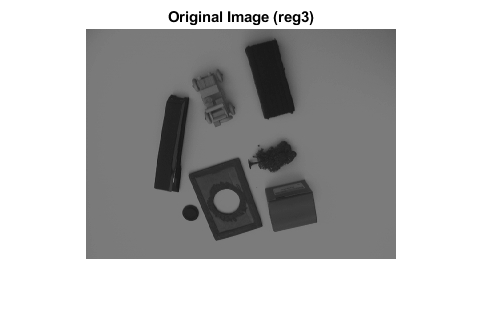

reg3 = imread('reg3.jpg');
reg3 = reg3(6:(end-5), 6:(end-5));
[H, W] = size(reg3);
figure, imshow(reg3), title("Original Image (reg3)");

- **Threshold image with niblack algorithm and noise reduction.**

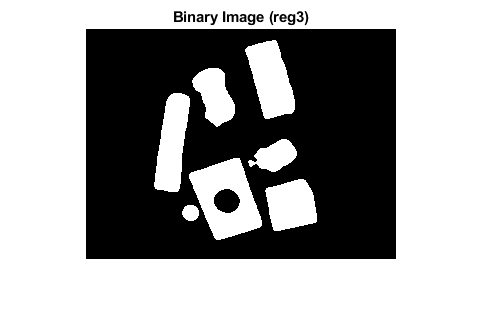

reg3 = niblack(reg3, 81, -0.1);
reg3 = gaussfilter(uint8(reg3*255), 5, 2);
reg3 = (reg3 > floor(255/2));
figure, imshow(reg3), title("Binary Image (reg3)"); 

- **Extract Connected Regions.**

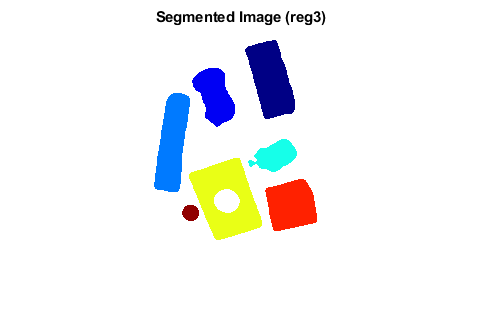

reg3 = raster_regioning(reg3);
figure, imshow(label2rgb(reg3)), title("Segmented Image (reg3)");

labels = unique(reg3);

## Image 1 - Get Statistics

for i = 2:length(labels)
    
    lbl = labels(i);
    
    % mask out other objects:
    obj = reg3;
    obj(obj ~= lbl) = false;
    obj = logical(obj);
    
    % start display:
    %figure, imshow(obj), title("Object ID: " + num2str(lbl));
    disp("Statistics for Object with ID: " + num2str(lbl));
    
    % create img with holes of object filled in:
    obj_filled = fill_img(obj);
    
    % create img with just holes of the object:
    holes_img = obj_filled - obj;
    holes_img = raster_regioning(holes_img);
    
    % find number of holes that have been regioned out:
    hole_num = length(unique(holes_img)) - 1; % subtract one for background.
    
    % Find Area, MBR, and Centroid:
    [maxX, maxY] = deal(-inf);
    [minX, minY] = deal(inf);
    [total_x, total_y, n, nf, p] = deal(0);
    for row = 1:H
        for col = 1:W
            if (obj(row, col)) % check actual object image
                
                n = n + 1;
                
                if(col > maxX)
                    maxX = col;
                end
                if(col < minX)
                    minX = col;
                end
                if(row > maxY)
                    maxY = row;
                end
                if(row < minY)
                    minY = row;
                end
                
                total_x = total_x + col;
                total_y = total_y + row;
            end
            
            if (obj_filled(row, col)) % check filled-in object image
                nf = nf + 1;
                if perimeter_pixel(obj_filled, row, col)
                    p = p + 1;
                end
            end
        end
    end
    
    disp("    Area = " + num2str(n));
    
    disp("    Number of Holes = " +num2str(hole_num));
    
    disp("    Area of Holes = " + num2str(nf - n));
    
    disp("    MBR = ");
    disp("      minX = " + num2str(minX));
    disp("      minY = " + num2str(minY));
    disp("      maxX = " + num2str(maxX));
    disp("      maxY = " + num2str(maxY));
    
    disp("    Centroid = ");
    disp("      [x,y] = [" + num2str(total_x/n) + ", " + num2str(total_y/n) + "]");
    
    disp("    Perimeter = " + num2str(p));
    
    disp("    Elongation = " + num2str( (p^2)/n ));
end

Statistics for Object with ID: 1


    Area = 2518


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 160


      minY = 12


      maxX = 209


      maxY = 90


    Centroid = 


      [x,y] = [185.5278, 50.9797]


    Perimeter = 254


    Elongation = 25.6219


Statistics for Object with ID: 11


    Area = 1565


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 107


      minY = 40


      maxX = 149


      maxY = 98


    Centroid = 


      [x,y] = [129.3284, 67.2818]


    Perimeter = 202


    Elongation = 26.0728


Statistics for Object with ID: 23


    Area = 2375


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 69


      minY = 65


      maxX = 104


      maxY = 163


    Centroid = 


      [x,y] = [86.8046, 115.0147]


    Perimeter = 266


    Elongation = 29.792


Statistics for Object with ID: 37


    Area = 962


    Number of Holes = 2


    Area of Holes = 21


    MBR = 


      minX = 163


      minY = 111


      maxX = 211


      maxY = 143


    Centroid = 


      [x,y] = [189.762, 127.5509]


    Perimeter = 166


    Elongation = 28.6445


Statistics for Object with ID: 56


    Area = 3364


    Number of Holes = 1


    Area of Holes = 475


    MBR = 


      minX = 104


      minY = 130


      maxX = 176


      maxY = 211


    Centroid = 


      [x,y] = [140.8083, 170.2562]


    Perimeter = 306


    Elongation = 27.8347


Statistics for Object with ID: 78


    Area = 2049


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 180


      minY = 151


      maxX = 231


      maxY = 202


    Centroid = 


      [x,y] = [205.8365, 176.7545]


    Perimeter = 204


    Elongation = 20.3104


Statistics for Object with ID: 91


    Area = 217


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 97


      minY = 177


      maxX = 113


      maxY = 192


    Centroid = 


      [x,y] = [105.2028, 184.4101]


    Perimeter = 62


    Elongation = 17.7143


## Image 2 - Get Regions

- **Import and crop image.**

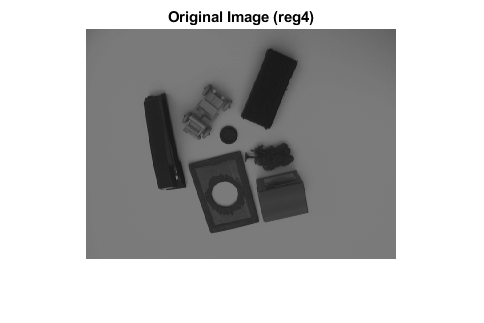

reg4 = imread('reg4.jpg');
reg4 = reg4(6:(end-5), 6:(end-5));
[H, W] = size(reg4);
figure, imshow(reg4), title("Original Image (reg4)");

- **Threshold image with niblack algorithm and noise reduction.**

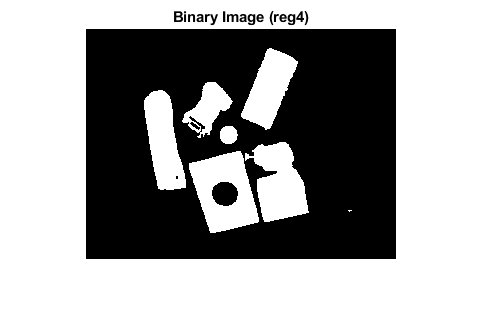

reg4 = niblack(reg4, 80, -0.1);
reg4 = gaussfilter(uint8(reg4*255), 5, 0.7);
reg4 = (reg4 > floor(255/2));

reg4 = bwmorph(reg4, 'diag');
reg4 = bwmorph(reg4, 'clean');
reg4 = bwmorph(reg4, 'fill');

figure, imshow(reg4), title("Binary Image (reg4)");

- **Extract Connected Regions.**

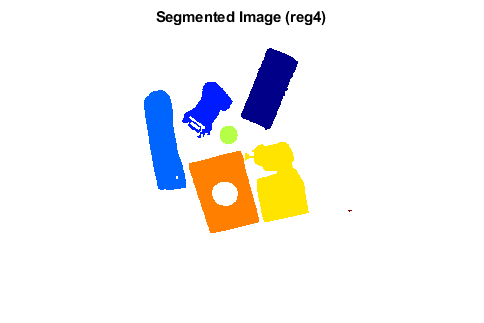

reg4 = raster_regioning(reg4);
figure, imshow(label2rgb(reg4)), title("Segmented Image (reg4)");

labels = unique(reg4);

## Image 2 - Get Statistics

for i = 2:length(labels)
    
    lbl = labels(i);
    
    % mask out other objects:
    obj = reg4;
    obj(obj ~= lbl) = false;
    obj = logical(obj);
    
    % start display:
    %figure, imshow(obj), title("Object ID: " + num2str(lbl));
    disp("Statistics for Object with ID: " + num2str(lbl));
    
    % create img with holes of object filled in:
    obj_filled = fill_img(obj);
    
    % create img with just holes of the object:
    holes_img = obj_filled - obj;
    holes_img = raster_regioning(holes_img);
    
    % find number of holes that have been regioned out:
    hole_num = length(unique(holes_img)) - 1; % subtract one for background.
    
    % Find Area, MBR, and Centroid:
    [maxX, maxY] = deal(-inf);
    [minX, minY] = deal(inf);
    [total_x, total_y, n, nf, p] = deal(0);
    for row = 1:H
        for col = 1:W
            if (obj(row, col)) % check actual object image
                
                n = n + 1;
                
                if(col > maxX)
                    maxX = col;
                end
                if(col < minX)
                    minX = col;
                end
                if(row > maxY)
                    maxY = row;
                end
                if(row < minY)
                    minY = row;
                end
                
                total_x = total_x + col;
                total_y = total_y + row;
            end
            
            if (obj_filled(row, col)) % check filled-in object image
                nf = nf + 1;
                if perimeter_pixel(obj_filled, row, col)
                    p = p + 1;
                end
            end
        end
    end
    
    disp("    Area = " + num2str(n));
    
    disp("    Number of Holes = " +num2str(hole_num));
    
    disp("    Area of Holes = " + num2str(nf - n));
    
    disp("    MBR = ");
    disp("      minX = " + num2str(minX));
    disp("      minY = " + num2str(minY));
    disp("      maxX = " + num2str(maxX));
    disp("      maxY = " + num2str(maxY));
    
    disp("    Centroid = ");
    disp("      [x,y] = [" + num2str(total_x/n) + ", " + num2str(total_y/n) + "]");
    
    disp("    Perimeter = " + num2str(p));
    
    disp("    Elongation = " + num2str( (p^2)/n ));
end

Statistics for Object with ID: 1


    Area = 2485


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 156


      minY = 20


      maxX = 212


      maxY = 101


    Centroid = 


      [x,y] = [183.9111, 59.8322]


    Perimeter = 277


    Elongation = 30.8769


Statistics for Object with ID: 17


    Area = 1295


    Number of Holes = 7


    Area of Holes = 96


    MBR = 


      minX = 97


      minY = 54


      maxX = 147


      maxY = 109


    Centroid = 


      [x,y] = [122.9629, 79.3305]


    Perimeter = 217


    Elongation = 36.3622


Statistics for Object with ID: 25


    Area = 2666


    Number of Holes = 2


    Area of Holes = 8


    MBR = 


      minX = 59


      minY = 62


      maxX = 100


      maxY = 161


    Centroid = 


      [x,y] = [78.132, 113.1995]


    Perimeter = 280


    Elongation = 29.4074


Statistics for Object with ID: 62


    Area = 263


    Number of Holes = 0


    Area of Holes = 0


    MBR = 


      minX = 135


      minY = 98


      maxX = 152


      maxY = 115


    Centroid = 


      [x,y] = [143.1445, 106.4677]


    Perimeter = 68


    Elongation = 17.5817


Statistics for Object with ID: 73


    Area = 3080


    Number of Holes = 3


    Area of Holes = 51


    MBR = 


      minX = 160


      minY = 114


      maxX = 223


      maxY = 193


    Centroid = 


      [x,y] = [193.7877, 154.7987]


    Perimeter = 333


    Elongation = 36.0029


Statistics for Object with ID: 84


    Area = 3417


    Number of Holes = 1


    Area of Holes = 495


    MBR = 


      minX = 104


      minY = 123


      maxX = 173


      maxY = 204


    Centroid = 


      [x,y] = [139.0632, 163.2865]


    Perimeter = 300


    Elongation = 26.3389


Statistics for Object with ID: 111


    Area = 5


    Number of Holes = 1


    Area of Holes = 46


    MBR = 


      minX = 263


      minY = 182


      maxX = 266


      maxY = 183


    Centroid = 


      [x,y] = [264.4, 182.2]


    Perimeter = 51


    Elongation = 520.2


## Discussion:

**Thresholding Method:** Since these were fairly complex grayscale images with multiple forground objects of differing intensities, I thought it would be best to implement a local thresholding algorithm. This algorithm computes a threshold for every pixel depending on the window of pixels surrounding it. The specific algorithm that I followed was the Niblack Algorithm. While I could not find the original paper by Niblack, I did find the mathematic algorithm on page 2 of "Efficient Implementation of Niblack Thresholding for MRI Brain Image Segmentation " by Senthilkumaran N and Kirubakaran C. I've sent the paper in with this report. 

After doing this local thresholding I noticed that the images were still a bit noisy. So I implemented a basic gaussian smoothing convolution function and used this to smooth out any irregularities and noise. This process alone worked very well for the first image. However, as you can see from my results of preprocessing image 2, I had a lot of problem separating objects from there shadows on the table. This caused 2 of the objects to be melded together in the binary image as if they were one object. This problem could have been solved by using a smaller window for local thresholding and perhaps using a smaller gaussian kernal for smoothing, but in this case and other manipulations of these parameters, I found that the noise was far too great. So I decided to cut my losses and deal with this mis-information with minimal noise. Addtionally in the second image, I encountered some problems when facing very bright protions of objects. These portions were considered holes or concavities by the thresholding algorithm as there didn't seem to be enough information to differentiate them from the color of the table in the background.

 Finally, for the second image I also used some of matlabs basic morphilogical functions to help clean up some of the noise. These were very basic functions that I did not see any need to reimplement them myself.

**Extract Connected Regions:** For this method I used the basic 2-pass raster method that we talked about in class. the slight modification that I made was that I prepadded the image so that I could reference pixels outside the original image for testing and not get an index out of bounds error. This did not affect the algorithm since all added pad rows and columns were all zeros. Once the region extraciton was finished I unpadded the image before returning it. I then used matlabs label2rgb() display function to color each region a different color in the display image. Before extracting statistics for each object I used the objects ID to mask out any other objects that might be present in the image. I then converted the now single object image to a logical matrix.

**Area: **This was simply computed adding up all the 1s in the single object image.

**Number of Holes:** For this statistic I used the following method:

- First fill in all the holes of the single object image with a signle raster scan.

- Subtract the original image from this filled in image. We now have an image that is 1's where the holes are and 0's everywhere else.

- I then preformed the same raster_regioning that was used to extract regions. This then tells me how many regions were recognized by looking at the holes.

**Area of Holes: **This was simply computed by summing all the 1s of the difference of the two images described in the previous statistic.

**MBR: **This was simply found by constantly updating the largest and smallest x and y values that were found to be in the object when doing a raster scan.

**Centroid: **Found by [total_x_coords / Area, total_y_coords/ Area]

**Perimeter: **This statistic was found by taking the previosly described single object image with all the holes filled in, and then simply counting up all the pixels that have any neighboring pixels that are not part of the object in a single raster scan.

**Elongation:** Perimeter^2 / Area.

Overall I think the first image was very successful with my methods, but the second image posed some problems with thresholding. This is due to a lack of information in the image (perhaps using rgb would have better helped determine forground objects) and due to my thresholding algorithm not being robust enough to separate all the objects correctly without any noise. However, the gathering of the image statistics worked well independent of the thresholding problems.